# Image processing - frequency domain

## 3. Linear filtering of Images

Taille d'image : 256x256

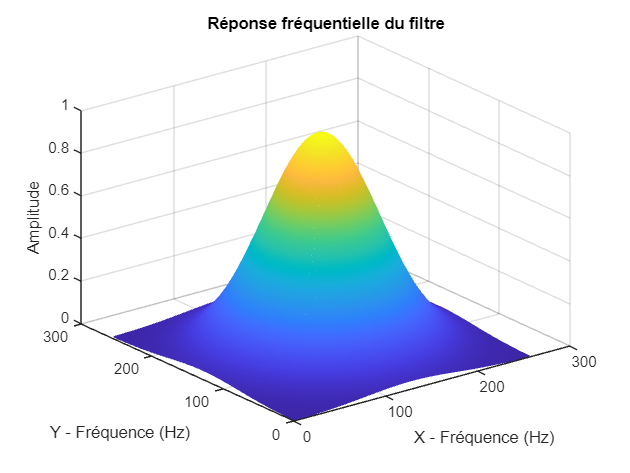

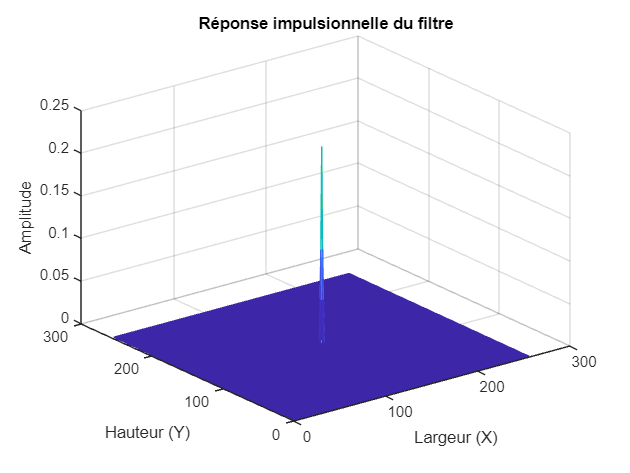

lp_design("gaussian",50,[256 256])

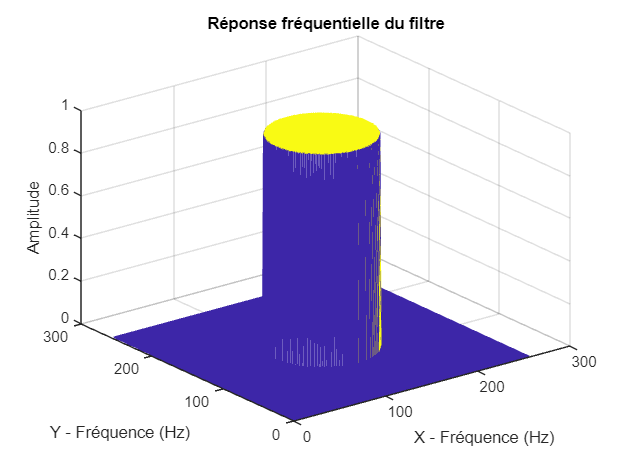

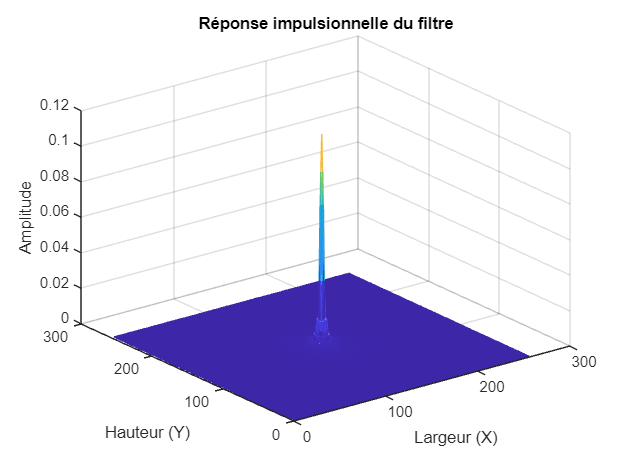

lp_design("ideal",50,[256 256])

%lp_design("btw",50,[256 256])

Filtre passe-haut à partir du code du filtre passe-bas : 

Un filtre passe-haut et un filtre passe-bas couvrent l'ensemble du spectre fréquentiel. L'amplitude maximale des fréquences étant de 1, pour obtenir la réponse fréquentielle du filtre passe-haut on soustrait la réponse fréquentielle du filtre passe-bas à 1.

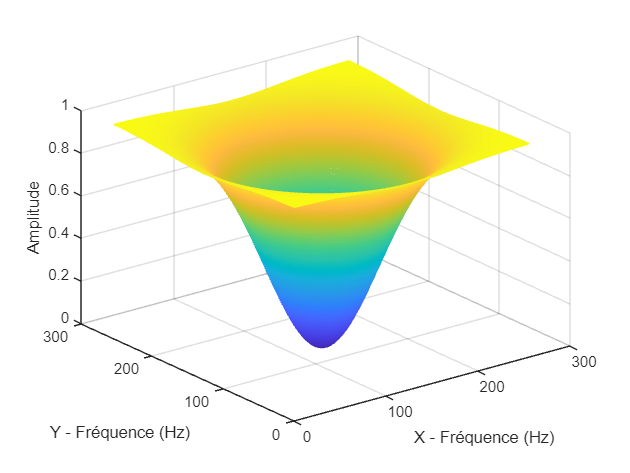

H_haut = fftshift(1- lpfilter('gaussian',256,256,50));

M = 256;
N = 256;

%Réponse fréquentielle
[X, Y] = meshgrid(1:N, 1:M);
figure(1);
mesh(X, Y, abs(H_haut));
xlabel('X - Fréquence (Hz)');
ylabel('Y - Fréquence (Hz)');
zlabel('Amplitude');

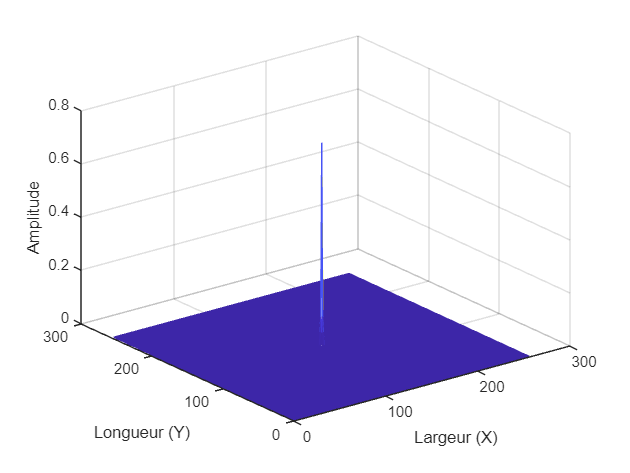


h_haut = fftshift(ifft2(H_haut));
%Réponse impulsionnelle
[X, Y] = meshgrid(1:N, 1:M);
figure(1);
mesh(X, Y, abs(h_haut));
xlabel('Largeur (X)');
ylabel('Longueur (Y)');
zlabel('Amplitude');

A.3.2 et A.3.3

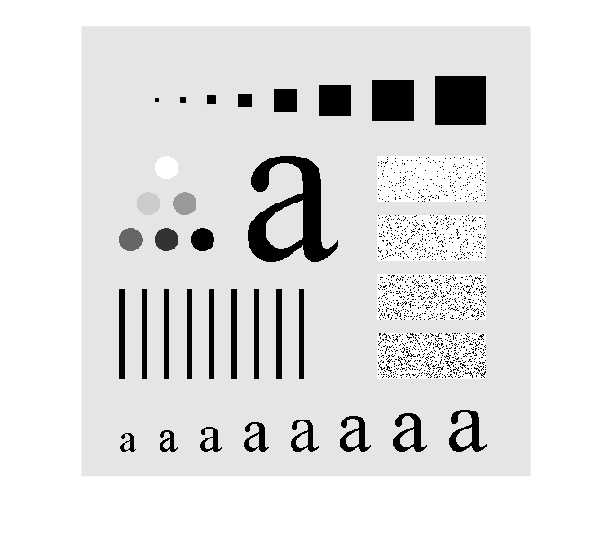

figtest = imread('Fig_test_pattern.tif', 'tiff');

figure
imshow(figtest);

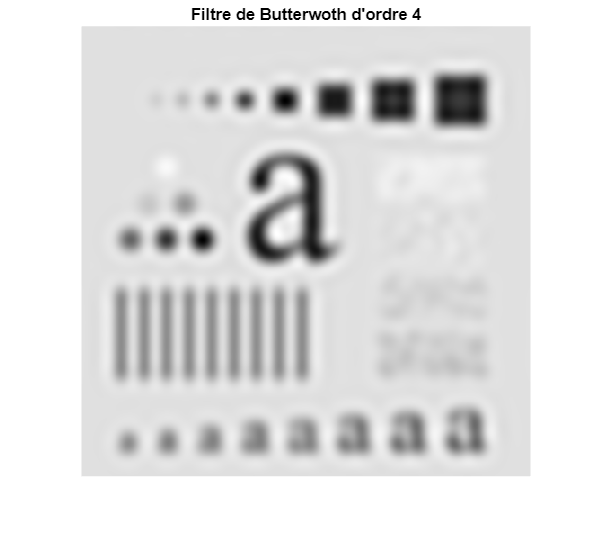


[M,N] = size(figtest);

H_btw = lpfilter('btw', M, N, 20, 4);
H_gauss = lpfilter('gaussian', M, N, 20);
H_ideal = lpfilter('ideal', M, N, 20);

im_f_btw = fft2(figtest).*H_btw;
im_f_gauss = fft2(figtest).*H_gauss;
im_f_ideal = fft2(figtest).*H_ideal;

imtest_f_btw = im2uint8(mat2gray(ifft2(im_f_btw)));
imtest_f_gauss = im2uint8(mat2gray(ifft2(im_f_gauss)));
imtest_f_ideal = im2uint8(mat2gray(ifft2(im_f_ideal)));

imshow(imtest_f_btw);
title("Filtre de Butterwoth d'ordre 4")

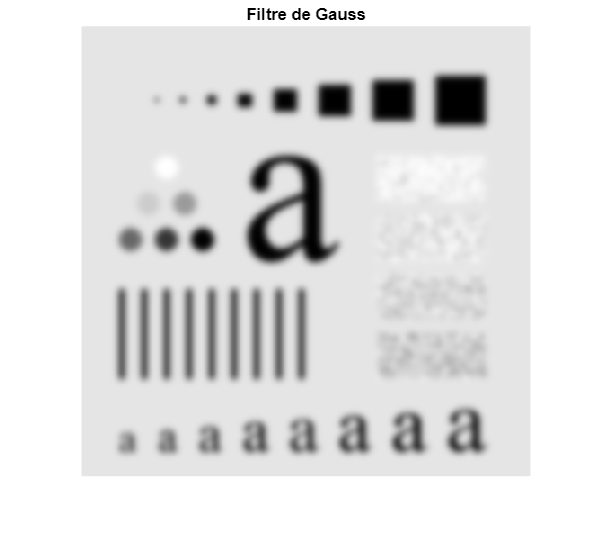

imshow(imtest_f_gauss);
title("Filtre de Gauss")

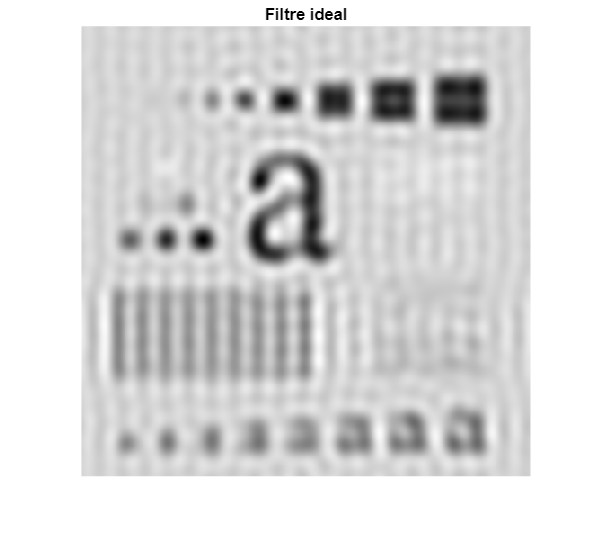


imshow(imtest_f_ideal);
title("Filtre ideal")


% H_gauss = lpfilter('btw', M, N, 10,4);
% im_f_gauss = fft2(figtest).*H_gauss;
% imtest_f_gauss = im2uint8(mat2gray(ifft2(im_f_gauss)));
% imshow(imtest_f_gauss);
% 
% H_gauss = lpfilter('btw', M, N, 60,4);
% im_f_gauss = fft2(figtest).*H_gauss;
% imtest_f_gauss = im2uint8(mat2gray(ifft2(im_f_gauss)));
% imshow(imtest_f_gauss);
% 
% H_gauss = lpfilter('btw', M, N, 100,4);
% im_f_gauss = fft2(figtest).*H_gauss;
% imtest_f_gauss = im2uint8(mat2gray(ifft2(im_f_gauss)));
% imshow(imtest_f_gauss);
% 
% H_gauss = lpfilter('btw', M, N, 150,4);
% im_f_gauss = fft2(figtest).*H_gauss;
% imtest_f_gauss = im2uint8(mat2gray(ifft2(im_f_gauss)));
% imshow(imtest_f_gauss);


Filtre passe-haut 

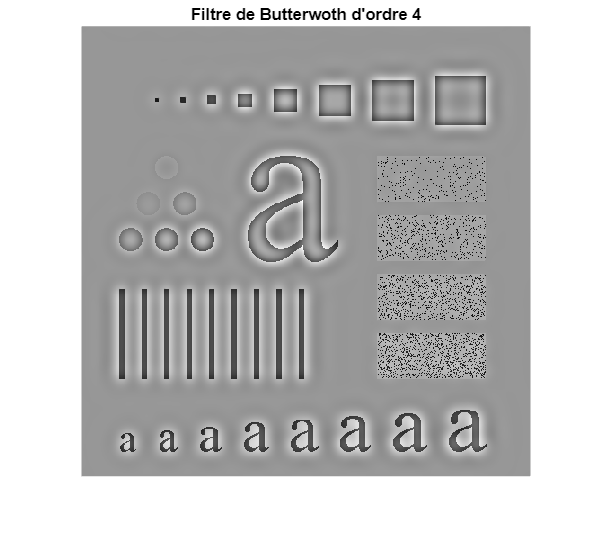

H_haut_g = 1- lpfilter('gaussian',M,N,20);
H_haut_btw = 1- lpfilter('btw',M,N,20,4);
H_haut_i = 1- lpfilter('ideal',M,N,20);

im_f_btw = fft2(figtest).*H_haut_btw;
im_f_gauss = fft2(figtest).*H_haut_g;
im_f_ideal = fft2(figtest).*H_haut_i;

imtest_f_btw = im2uint8(mat2gray(ifft2(im_f_btw)));
imtest_f_gauss = im2uint8(mat2gray(ifft2(im_f_gauss)));
imtest_f_ideal = im2uint8(mat2gray(ifft2(im_f_ideal)));

imshow(imtest_f_btw);
title("Filtre de Butterwoth d'ordre 4")

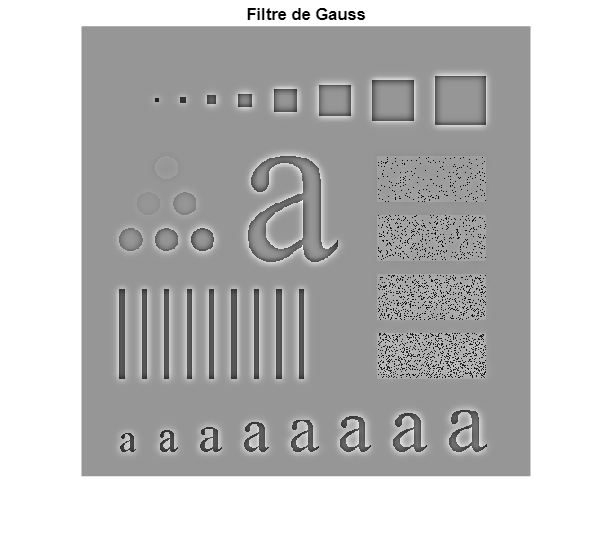

imshow(imtest_f_gauss);
title("Filtre de Gauss")

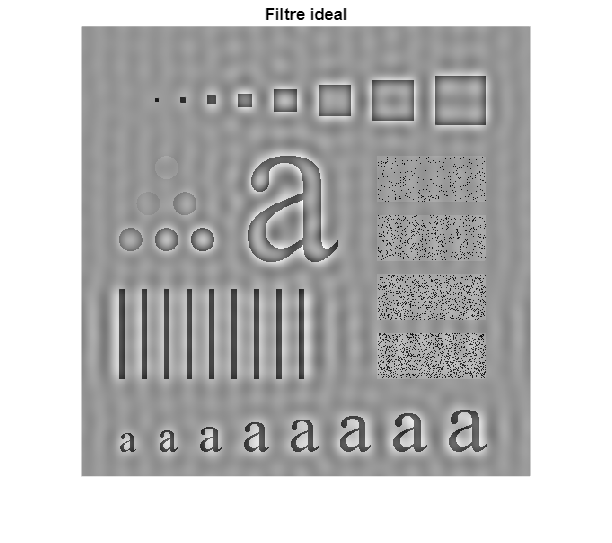


imshow(imtest_f_ideal);
title("Filtre ideal")

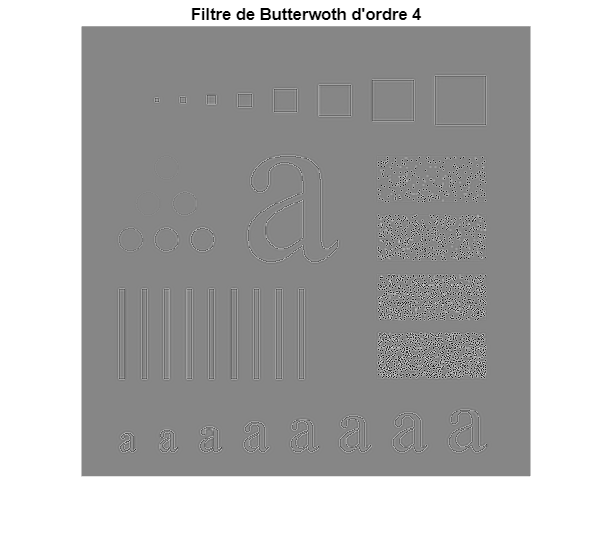





H_haut_btw = 1- lpfilter('btw',M,N,150,4);

im_f_btw = fft2(figtest).*H_haut_btw;

imtest_f_btw = im2uint8(mat2gray(ifft2(im_f_btw)));

imshow(imtest_f_btw);
title("Filtre de Butterwoth d'ordre 4")